A=[[1,3,4,76,88,3,54,6]    
[2,54,3,656,8,9999,65,3]
[5,34,3,6,77,4,234,9999]]

A =            1           3           4          76          88           3          54           6
           2          54           3         656           8        9999          65           3
           5          34           3           6          77           4         234        9999



B = zeros(8760, size(A,2));
B(A(:,1),:) = A

B =            1           3           4          76          88           3          54           6
           2          54           3         656           8        9999          65           3
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           5          34           3           6          77           4         234        9999
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0



B(B(:,1)==0,2:end) = 9999;
B(:,1) = 1:8760   % (Used 1:5 in my example below)

B =            1           3           4          76          88           3          54           6
           2          54           3         656           8        9999          65           3
           3        9999        9999        9999        9999        9999        9999        9999
           4        9999        9999        9999        9999        9999        9999        9999
           5          34           3           6          77           4         234        9999
           6        9999        9999        9999        9999        9999        9999        9999
           7        9999        9999        9999        9999        9999        9999        9999
           8        9999        9999        9999        9999        9999        9999        9999
           9        9999        9999        9999        9999        9999        9999        9999
          10        9999        9999        9999        9999        9999        9999        9999


conn_mat

conn_mat =          0    0.2276    0.1541    0.0061    0.0937    0.0350    0.2573    0.1965    0.1088    0.1877    0.0495    0.2392    0.1569    0.0791    0.2081    0.0894    0.2277    0.1920    0.1207    0.1897    0.2547    0.1288    0.0134    0.2672    0.1940    0.1605    0.1608    0.1596    0.2777    0.2048    0.0139    0.0069    0.1372    0.1955    0.2153    0.0138    0.0780    0.0338    0.1138    0.1897    0.1636    0.0720    0.1362    0.0827    0.0759    0.1236    0.1856    0.1857    0.0375    0.2441
    0.2276         0    0.0886    0.2209    0.2455    0.1344    0.0929    0.1192    0.2012    0.2393    0.0750    0.2606    0.2895    0.2753    0.0567    0.0541    0.1919    0.1106    0.1798    0.1128    0.2192    0.0731    0.2546    0.2164    0.1795    0.2251    0.2246    0.2258    0.1320    0.0505    0.1831    0.2218    0.1545    0.1298    0.0233    0.2129    0.1923    0.1279    0.1947    0.2296    0.2936    0.2764    0.1154    0.2207    0.2194    0.1886    0.1203    0.1184    0.24

B = NaN(64, size(conn_mat, 2));
intersect = ismember(data_load.allart.channel, source_conn.label);
intersect_idx = find(intersect == 1)

intersect_idx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


B(intersect_idx, :) = conn_mat

B =          0    0.2276    0.1541    0.0061    0.0937    0.0350    0.2573    0.1965    0.1088    0.1877    0.0495    0.2392    0.1569    0.0791    0.2081    0.0894    0.2277    0.1920    0.1207    0.1897    0.2547    0.1288    0.0134    0.2672    0.1940    0.1605    0.1608    0.1596    0.2777    0.2048    0.0139    0.0069    0.1372    0.1955    0.2153    0.0138    0.0780    0.0338    0.1138    0.1897    0.1636    0.0720    0.1362    0.0827    0.0759    0.1236    0.1856    0.1857    0.0375    0.2441
    0.2276         0    0.0886    0.2209    0.2455    0.1344    0.0929    0.1192    0.2012    0.2393    0.0750    0.2606    0.2895    0.2753    0.0567    0.0541    0.1919    0.1106    0.1798    0.1128    0.2192    0.0731    0.2546    0.2164    0.1795    0.2251    0.2246    0.2258    0.1320    0.0505    0.1831    0.2218    0.1545    0.1298    0.0233    0.2129    0.1923    0.1279    0.1947    0.2296    0.2936    0.2764    0.1154    0.2207    0.2194    0.1886    0.1203    0.1184    0.2479    0


C = NaN(size(B, 1), 64);
C(:, intersect_idx) = B

C =          0    0.2276    0.1541    0.0061    0.0937    0.0350    0.2573    0.1965    0.1088    0.1877    0.0495    0.2392    0.1569    0.0791    0.2081    0.0894    0.2277    0.1920    0.1207    0.1897    0.2547    0.1288    0.0134    0.2672    0.1940    0.1605    0.1608    0.1596    0.2777    0.2048    0.0139       NaN    0.0069    0.1372    0.1955    0.2153    0.0138    0.0780    0.0338       NaN    0.1138    0.1897       NaN    0.1636    0.0720    0.1362    0.0827    0.0759    0.1236    0.1856
    0.2276         0    0.0886    0.2209    0.2455    0.1344    0.0929    0.1192    0.2012    0.2393    0.0750    0.2606    0.2895    0.2753    0.0567    0.0541    0.1919    0.1106    0.1798    0.1128    0.2192    0.0731    0.2546    0.2164    0.1795    0.2251    0.2246    0.2258    0.1320    0.0505    0.1831       NaN    0.2218    0.1545    0.1298    0.0233    0.2129    0.1923    0.1279       NaN    0.1947    0.2296       NaN    0.2936    0.2764    0.1154    0.2207    0.2194    0.1886    0

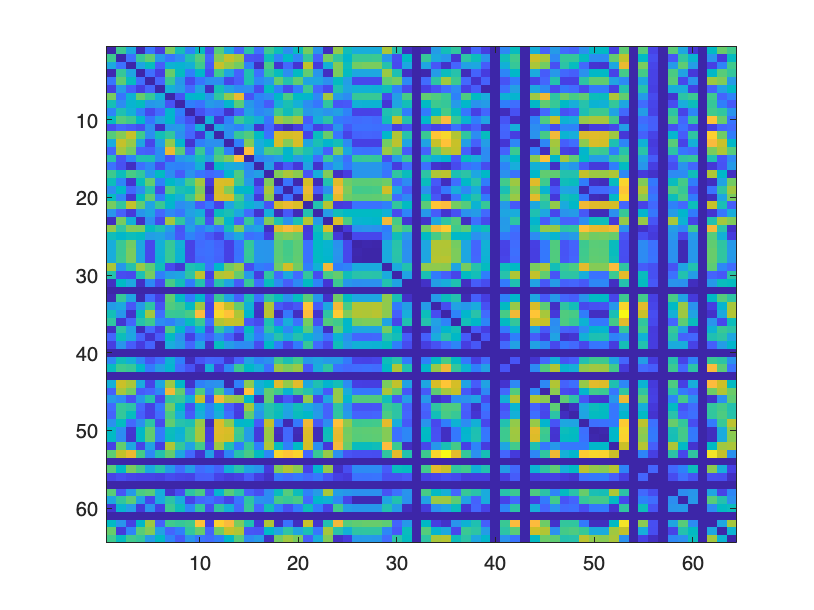

imagesc(C)